# 2. Locating a moving target

## 2.0 Initialization

clear;

## 2.1 The setup

## 2.2 Distance from a critical point

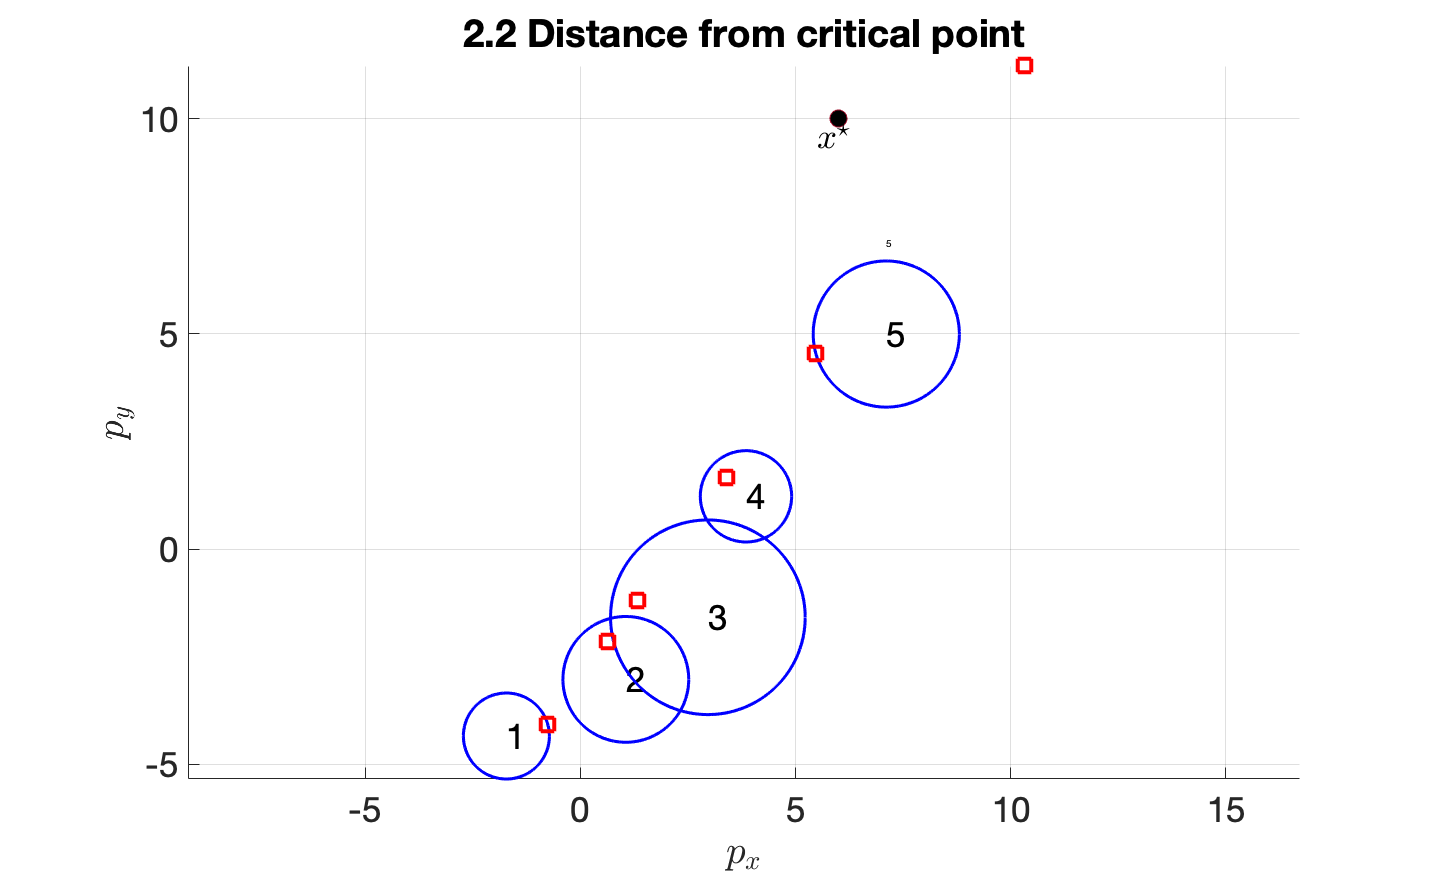

% Given data
t_k = [0 1 1.5 3 4.5];
c_k = [-1.7210 -4.3454; 1.0550 -3.0293; 2.9619 -1.5857; 3.8476 1.2253; 7.1086 4.9975]';
R_k = [0.9993 1.4618 2.2617 1.0614 1.6983];
t_star = 8;
x_star = [6;10];

cvx_begin quiet
    % optimization variables
    variables p0(2,1) v(2,1)
    % cost function
    minimize(norm(p0+t_star*v-x_star));
    % subject to
    for k = 1:length(t_k)
        norm(p0+t_k(k)*v-c_k(:,k)) <= R_k(k);
    end
cvx_end

p_k = p0+kron([t_k t_star],v);
minimumDistance = norm(p0+t_star*v-x_star);

% ---------- Plot result ----------
% trajectory
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
set(gca,'FontSize',35);
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
axis equal;
title('2.2 Distance from critical point');
theta = 0:0.01:2*pi;
for k = 1:length(t_k)
    p = plot(R_k(k)*cos(theta)+c_k(1,k),R_k(k)*sin(theta)+c_k(2,k),'Color','blue');
    p.LineWidth = 3;
    text(c_k(1,k),c_k(2,k),sprintf('%d',k),'FontSize',25);
end
scatter(p_k(1,:),p_k(2,:),300,'s','red','LineWidth',4);
scatter(x_star(1),x_star(2),300,'o','MarkerFaceColor','black');
text(x_star(1)-1,x_star(2)-1,'$x^{\star}$','Interpreter','latex','FontSize',35);
text(c_k(1,k),c_k(1,k),sprintf('%d',k));
ylabel('$p_y$','Interpreter','latex');
xlabel('$p_x$','Interpreter','latex');
saveas(gcf,'./locating_a_moving_target_data/2_2.fig');
saveas(gcf,'./locating_a_moving_target_data/2_2.png');
hold off;


fprintf("The minimum distance to x_star at t_star is %f with: \n",minimumDistance);

The minimum distance to x_star at t_star is 4.494781 with: 


p0

p0 =    -0.7597
   -4.0725


v

v =     1.3855
    1.9125


save('./locating_a_moving_target_data/2_2_data.mat','minimumDistance','p0','v');
